clear, clc, close all;
rng('default');
defaultseed = rng;


cali_data_raw = readtable("data/california_housing.csv");

fprintf('Num of instances: %d', size(cali_data_raw,1));

Num of instances: 20640

fprintf('Num of features: %d', size(cali_data_raw,2)-1);

Num of features: 9


cali_data_raw.Properties.VariableNames

ans = 1×10 cell array
    {'longitude'}    {'latitude'}    {'housing_median_age'}    {'total_rooms'}    {'total_bedrooms'}    {'population'}    {'households'}    {'median_income'}    {'median_house_value'}    {'ocean_proximity'}



summary(cali_data_raw);

Variables:

    longitude: 20640×1 double

        Values:

            Min       -124.35 
            Median    -118.49 
            Max       -114.31 

    latitude: 20640×1 double

        Values:

            Min        32.54  
            Median     34.26  
            Max        41.95  

    housing_median_age: 20640×1 double

        Values:

            Min           1   
            Median       29   
            Max          52   

    total_rooms: 20640×1 double

        Values:

            Min            2  
            Median      2127  
            Max        39320  

    total_bedrooms: 20640×1 double

        Values:

            Min             1     
            Median          435   
            Max             6445  
            NumMissing      207   

    population: 20640×1 double

        Values:

            Min            3  
            Median      1166  
   

countlabels(categorical(cali_data_raw.ocean_proximity))

Error using  . 
Unrecognized table variable name 'ocean_proximity'.

fprintf('dropping ocean_proximity column');
cali_data_raw.ocean_proximity = [];

fprintf('drop rows with nan\n');
cali_data = rmmissing(cali_data_raw);
fprintf('%d rows dropped with Nan values', size(cali_data_raw,1)-size(cali_data,1));

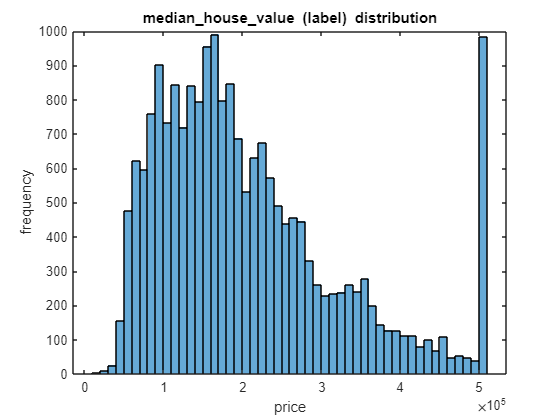

figure(1);
histogram(cali_data.median_house_value);
title('median\_house\_value (label) distribution');
xlabel('price');
ylabel('frequency');

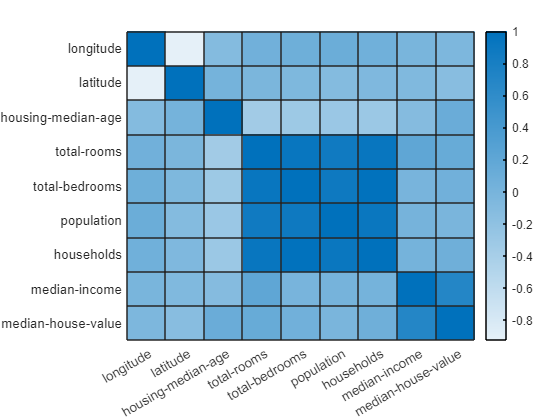

h=heatmap(corr(cali_data{:,:}));
h.XDisplayLabels = strrep(cellstr(cali_data.Properties.VariableNames),'_','-');
h.YDisplayLabels = strrep(cellstr(cali_data.Properties.VariableNames),'_','-');

total_rooms_pop_norm = cali_data.total_rooms./cali_data.population;
total_bedrooms_pop_norm = cali_data.total_bedrooms./cali_data.population;
cali_data.total_rooms_pop_norm = total_rooms_pop_norm;
cali_data.total_bedrooms_pop_norm = total_bedrooms_pop_norm

cali_data = 20433×11 table
    longitude    latitude    housing_median_age    total_rooms    total_bedrooms    population    households    median_income    median_house_value    total_rooms_pop_norm    total_bedrooms_pop_norm
    _________    ________    __________________    ___________    ______________    __________    __________    _____________    __________________    ____________________    _______________________

     -122.23      37.88              41                880              129             322           126          8.3252            4.526e+05                2.7329                   0.40062        
 

cali_data = [cali_data(:,1:5) cali_data(:,10:11) cali_data(:,6:9)];

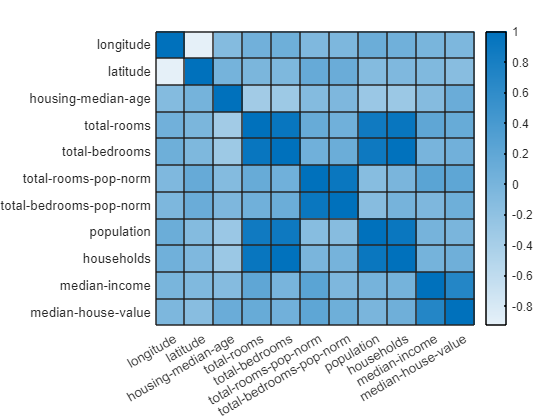

norm_cali_data = normalize(cali_data);
h=heatmap(corr(cali_data{:,:}));
h.XDisplayLabels = strrep(cellstr(cali_data.Properties.VariableNames),'_','-');
h.YDisplayLabels = strrep(cellstr(cali_data.Properties.VariableNames),'_','-');